# compareBB

Script to load previously saved splWindow .mat files and compare broadband metrics

clear all
addpath 'C:\Users\510PAS\PhD\Code\NW\SPL_windows'
tog.saveIt = 'yes';

par.fontSize = 14;                          %font size for plots
par.lineWidth = 2;                          %width of means polarplot line
par.smooth = 120;                            %number of windows to use for smoothing means
par = setPars;

% C:\Users\510PAS\PhD\Data\NW_2019\' tog.VOI '.mat'
%cd H:\PhD\NW\proc\Combined
cd H:\PhD\NW\proc
files = dir('*.mat');

lobData = cell(size(files));
for ii=1:length(files)
    aFileData = load(files(ii).name);
    lobData{ii} = aFileData; %.data;
end

minSpd = min(cell2mat(cellfun(@(x) min(x.SPL.sog), lobData, 'UniformOutput', false)));
maxSpd = max(cell2mat(cellfun(@(x) max(x.SPL.sog), lobData, 'UniformOutput', false)));

minBB = min(cell2mat(cellfun(@(x) min(x.BB(1,:)), lobData, 'UniformOutput', false)));
maxBB = max(cell2mat(cellfun(@(x) max(x.BB(1,:)), lobData, 'UniformOutput', false)));

par.bbLim = [minBB-10 maxBB];                      %range for broadband polar plot

### Broadband

%p = gobjects(length(lobData)+1,4);
h = figure('units','normalized','outerposition',[0 0 0.8 0.8])

h =   Figure (44) with properties:

      Number: 44
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0048 0.0076 0.7905 0.7629]
       Units: 'normalized'

  Show all properties


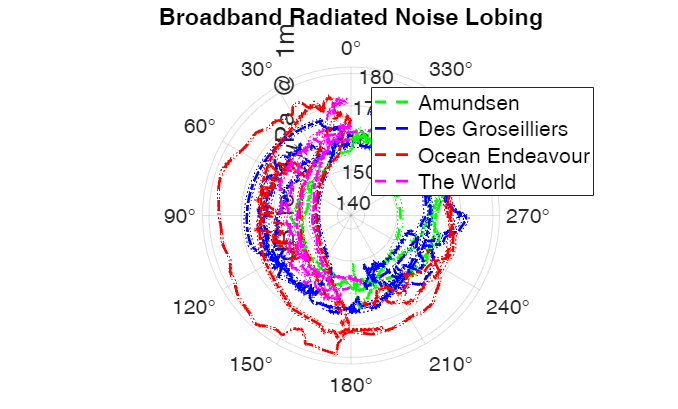

for i=1:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = smoothdata(mean(lobData{i,1}.BB,1),'gaussian',par.smooth);
    stddev = smoothdata(std(lobData{i,1}.BB,0,1),'gaussian',par.smooth);
    if contains(files(i).name,"Amundsen")
        col='g';
        shipName='Amundsen';
    elseif contains(files(i).name,"DesGros")
        col='b';
        shipName='Des Groseilliers';
    elseif contains(files(i).name,"OcEnd")
        col='r';
        shipName='Ocean Endeavour';
    elseif contains(files(i).name,"World")
        col='m';
        shipName='The World';
    end
    if contains(files(i).name,"AAA1")
        shape='--';
    elseif contains(files(i).name,"AAA2")
        shape='-.';
    end

    polarplot(rads,levels,'LineStyle',shape,'LineWidth',par.lineWidth,'Color',col,'DisplayName',shipName);
    hold on
    polarplot(rads,levels+stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col,'HandleVisibility','off');
    polarplot(rads,levels-stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col,'HandleVisibility','off');
end
rlim(par.bbLim)
title('Broadband Radiated Noise Lobing')
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize;
ax.ThetaZeroLocation = 'top'; ax.ThetaDir = 'clockwise';
legend(legendUnq(),'FontSize',par.fontSize,'Location','best')
saveas(h, fullfile(par.figPath,'AllContactsBBLobing.tif'))
saveas(h, fullfile(par.figPath,'AllContactsBBLobing'))

Speed correlation for broadband

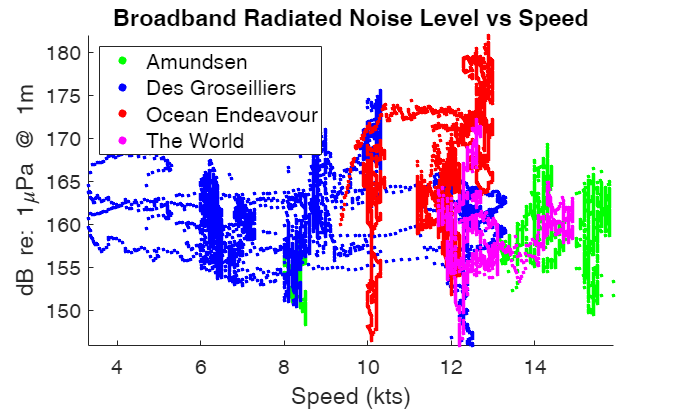

h = figure('units','normalized','outerposition',[0 0 0.8 0.8]);
sz = 8;
for i=1:length(files)
    speed = lobData{i,1}.SPL.sog';
    levels = lobData{i,1}.BB;
    if contains(files(i).name,"Amundsen")
        col='g';
        shipName='Amundsen';
    elseif contains(files(i).name,"DesGros")
        col='b';
        shipName='Des Groseilliers';
    elseif contains(files(i).name,"OcEnd")
        col='r';
        shipName='Ocean Endeavour';
    elseif contains(files(i).name,"World")
        col='m';
        shipName='The World';
    end
    hold on
    scatter(speed,levels(1,:),sz,col,'filled','DisplayName',shipName);
    %Linear fit
%     hold on
%     p=polyfit(speed,levels(1,:),1);
%     x1 = [minSpd maxSpd];
%     y1 = polyval(p,x1);
%     plot(x1,y1,'Color',col,'LineStyle',shape,'HandleVisibility','off')
end
title('Broadband Radiated Noise Level vs Speed')
ylabel('dB re: 1\muPa @ 1m')
xlabel('Speed (kts)')
xlim([minSpd maxSpd])
ylim([minBB maxBB])
% lsFit = lsline;
% for i=1:length(files)
%     lsFit(i).Color=col(i);
%     lsFit(i).HandleVisibility = 'off';
%     lsFit(i).LineStyle = shape(2*i-1:2*i);
% end
ax = gca;
ax.FontSize = par.fontSize;
legend(legendUnq(),'FontSize',par.fontSize,'Location','Northwest')
% lgd = legend(legendUnq())
% lgd.NumColumns = 2;
saveas(h, fullfile(par.figPath,'AllContactsRNLvsSpd.tif'))

saveas(h, fullfile(par.figPath,'AllContactsRNLvsSpd'))